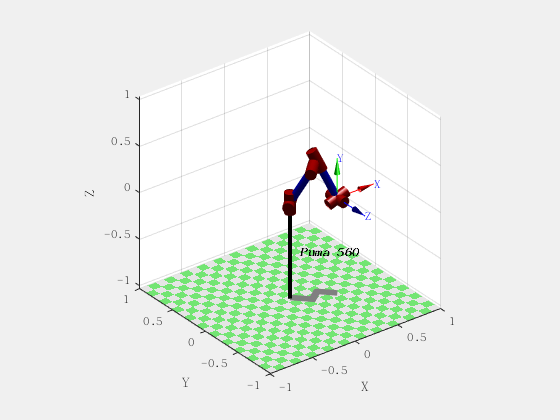

import ETS3.*
import ETS2.*
% 获得一个puma560对象
mdl_puma560
% 新建两个移动
T1 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T2 = SE3(0.4, -0.2, 0) * SE3.Rx(pi/2);
% 换算为关节
q1 = p560.ikine6s(T1);
q2 = p560.ikine6s(T2);
t = [0:0.05:2]';
% 平滑插值
q = mtraj(@tpoly, q1, q2, t);
q = mtraj(@lspb, q1, q2, t);
% 获得关节序列
q = jtraj(q1, q2, t); 
% 获得加速度和速度
[q,qd,qdd] = jtraj(q1, q2, t);
q = p560.jtraj(T1, T2, t);
% 画出轨迹图
p560.plot(q)

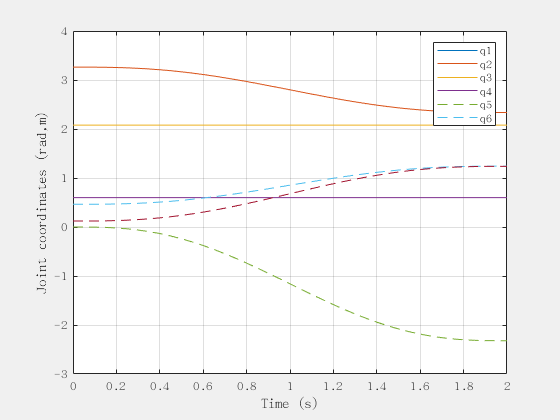

plot(t, q(:,2))
% 随时间变化的关节角
qplot(t, q);

% 正运动学
T = p560.fkine(q);
p = T.transl;
about(p)

p [double] : 41x3 (984 bytes)


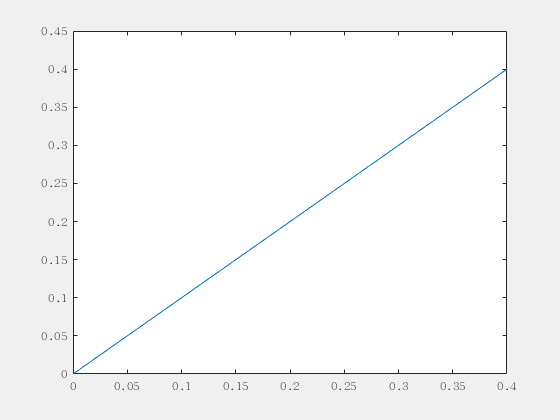

plot(p(1,:), p(2,:))

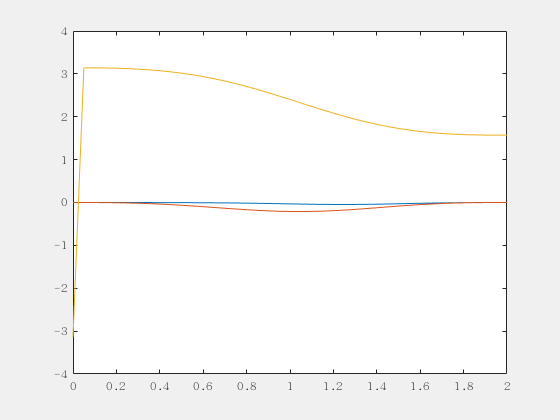

plot(t, T.torpy('xyz'))

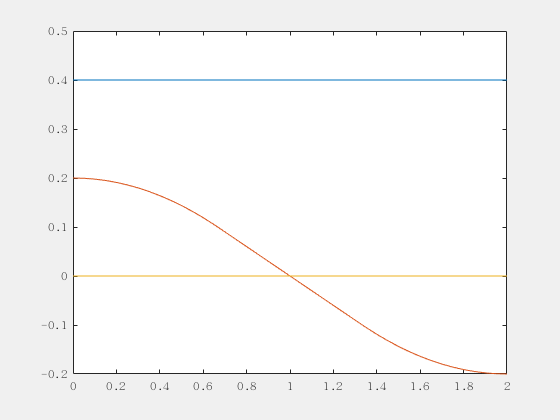

Ts = ctraj(T1, T2, length(t));
plot(t, Ts.transl);

plot(t, Ts.torpy('xyz'));
qc = p560.ikine6s(Ts);
% sl_jspace
T1 = SE3(0.5, 0.3, 0.44) * SE3.Ry(pi/2);
T2 = SE3(0.5, -0.3, 0.44) * SE3.Ry(pi/2);
% 求笛卡尔运动
Ts = ctraj(T1, T2, length(t));
% 获得关节序列
qc = p560.ikine6s(Ts);

qc =     3.4218    1.8818   -0.3310   -1.5015    0.2808   -1.6429
    3.4203    1.8807   -0.3295   -1.5023    0.2794   -1.6420
    3.4160    1.8774   -0.3252   -1.5048    0.2750   -1.6394
    3.4087    1.8719   -0.3181   -1.5089    0.2677   -1.6350
    3.3985    1.8643   -0.3083   -1.5147    0.2573   -1.6288
    3.3852    1.8548   -0.2960   -1.5224    0.2439   -1.6207
    3.3688    1.8435   -0.2816   -1.5322    0.2274   -1.6104
    3.3492    1.8305   -0.2652   -1.5446    0.2077   -1.5976
    3.3262    1.8162   -0.2473   -1.5604    0.1846   -1.5813
    3.2997    1.8007   -0.2282   -1.5815    0.1581   -1.5599


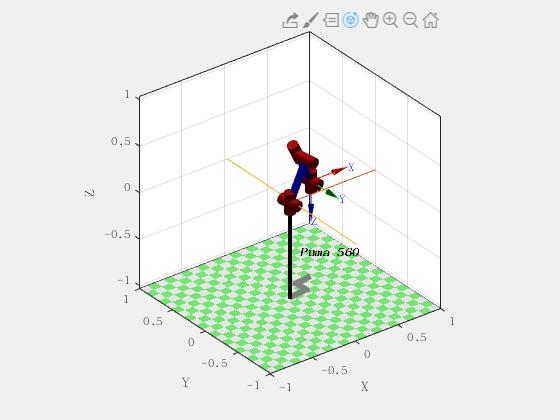

m = p560.maniplty(qc);
T = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
% 位形转换，分别确定右手左手在上位形对应的关节坐标
qr = p560.ikine6s(T, 'ru');
ql = p560.ikine6s(T, 'lu');
% 创建路径
q = jtraj(qr, ql, t);
% 画图
p560.plot(q)

% % 计算标准状态（灵巧工作姿态）下的世界坐标系下的雅克比矩阵,'eul'指欧拉角
% J = p560.jacob0(qn, 'eul')
% % teach模式
% % p560.teach(qn)
% % 末端坐标下的雅克比矩阵
% p560.jacobe(qn)
% % 奇异点，雅克比矩阵行列式值为0，q6和q4耦合
% J = p560.jacob0(qr)
% det(J)
% jsingu(J)
% % 可操作性分析
% J = p560.jacob0(qn)
% J = J(1:3, :)
% % 画出速度椭球和旋转速度椭球
% p560.vellipse(qn, 'trans')
% % p560.vellipse(qn, 'rot');
% % 判断是否具有可操作性
% m = p560.maniplty(qn)
% J = p560.jacob0(qr);
% J = J(1:3, :);
% % 画出速度椭球
% % p560.vellipse(qr, 'trans');
% % 判断是否具有可操作性
% m = p560.maniplty(qr)
% L1 = 0; L2 = -0.2337; L3 = 0.4318; L4 = 0.0203; L5 = 0.0837; L6 = 0.4318;
% E3 = Tz(L1) * Rz('q1') * Ry('q2') * Ty(L2) * Tz(L3) * Ry('q3')* Tx(L4) * Ty(L5) * Tz(L6) * Rz('q4') * Ry('q5') * Rz('q6');
% E3.fkine([0 0 0 0 0 0]);
% L = Revolute('a', 1);
% robot = SerialLink( [ Revolute('a', 1) Revolute('a', 1) ],'name', 'my robot');
% robot.fkine([30 40], 'deg');
% a1 = 1; a2 = 1;
% TE0 = SE2(a1+a2, 0, 0);
% S1 = Twist( 'R', [0 0] );
% S2 = Twist( 'R', [a1 0] );
% TE = S1.T(30, 'deg') * S2.T(40, 'deg') * TE0;

% mdl_puma560
% p560
% p560.plot(qz)
% TE = p560.fkine(qz)
% p560.tool = SE3(0, 0, 0.2);
% p560.fkine(qz)
% p560.base = SE3(0, 0, 30*0.0254);
% p560.fkine(qz)
% p560.base = SE3(0,0,3) * SE3.Rx(pi);
% p560.fkine(qz)


% mdl_puma560
% qn
% T = p560.fkine(qn)
% qi = p560.ikine6s(T)
% p560.fkine(qi)
% qi = p560.ikine6s(T, 'ru')
% p560.ikine6s( SE3(3, 0, 0) )
% q = [0 pi/4 pi 0.1 0 0.2];
% p560.ikine6s(p560.fkine(q), 'ru')
% q(4)+q(6)
% T = p560.fkine(qn)
% qi = p560.ikine(T)
% qn
% p560.fkine(qi)
% p560.plot(qi)
% qi = p560.ikine(T, 'q0', [0 0 3 0 0 0])